# Experiment 8.1

## Name: Tim Roche

## Objectives

To verify the effect of open-loop poles and zeros upon the shape of the root locus. To verify the root locus as a tool for estimating the effect of open-loop gain upon the transient response of closed-loop systems.    

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

*Sketch two possibilities for the root locus of a unity negative-feedback system with the open-loop pole-zero configuration shown in Figure P8.21*

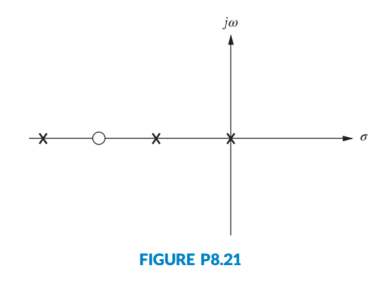

**Answer:**

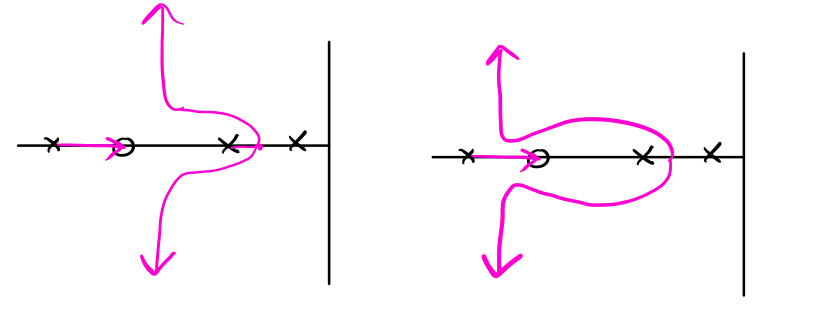

### Problem 2

*If the open-loop system of Prelab 1 is *$G(s) = \frac{K(s+1.5)}{s(s+0.5)(s+10)}$, estimate the precent overshoot at the following values of gain, $K: 20, 50, 85, 200, 700$.

**Answer:**

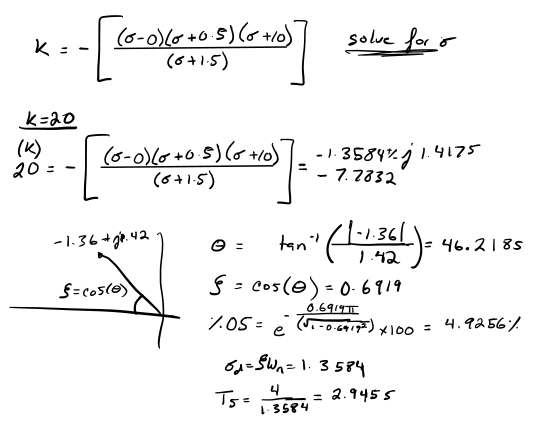

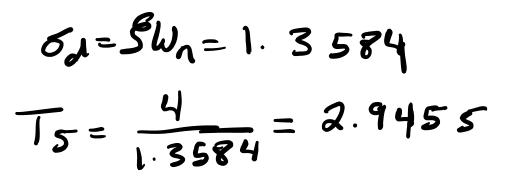

*Process was automatted using matlab for all other values of k*

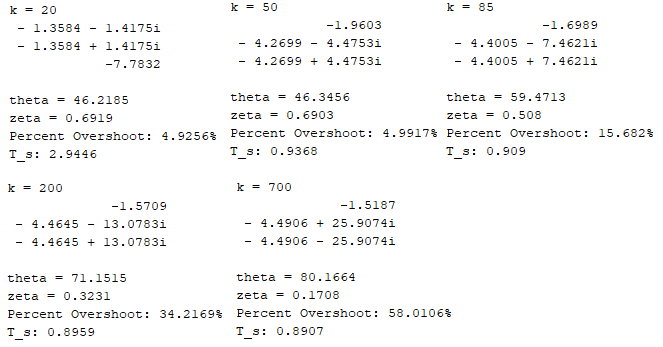

## Lab

### Problem 1

*Using MATLAB's SISO Design Tool, set up a negative unity feedback system with *$G(s) = \frac{K(s+6)}{s(s+0.5)(s+10)}$* to produce a root locus. For convenience, set up the zero at 6 using SISO Design Tool’s compensator function by simply dragging a zero to -6 on the resulting root locus. Print the root locus for the zero at -6. Move the zero to the following locations and print out a root locus at each location: -2, -1.5, -1.37, and -1.2.  *

s = tf("s");
C = (s+6);
G = 1/((s)*(s+0.5)*(s+10));
%controlSystemDesigner(G,C,1,1);

**Zero @ -6**

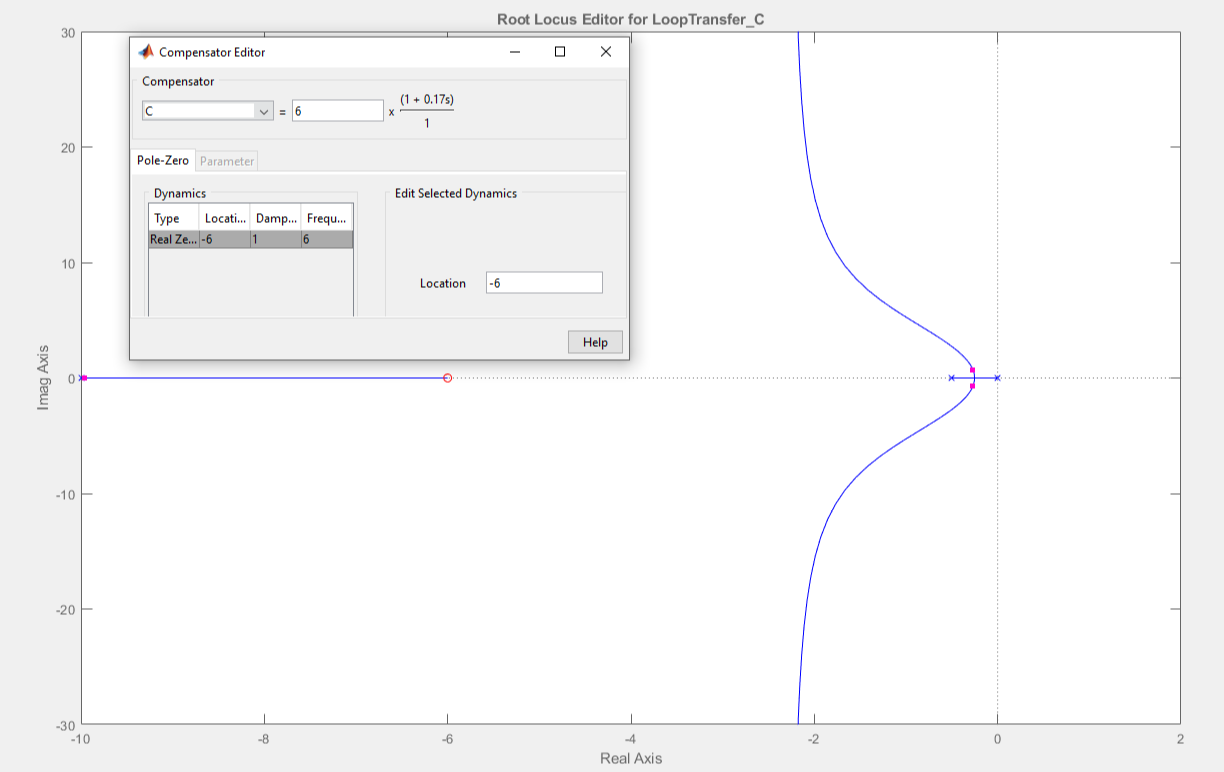

**Zero @ -2**

### 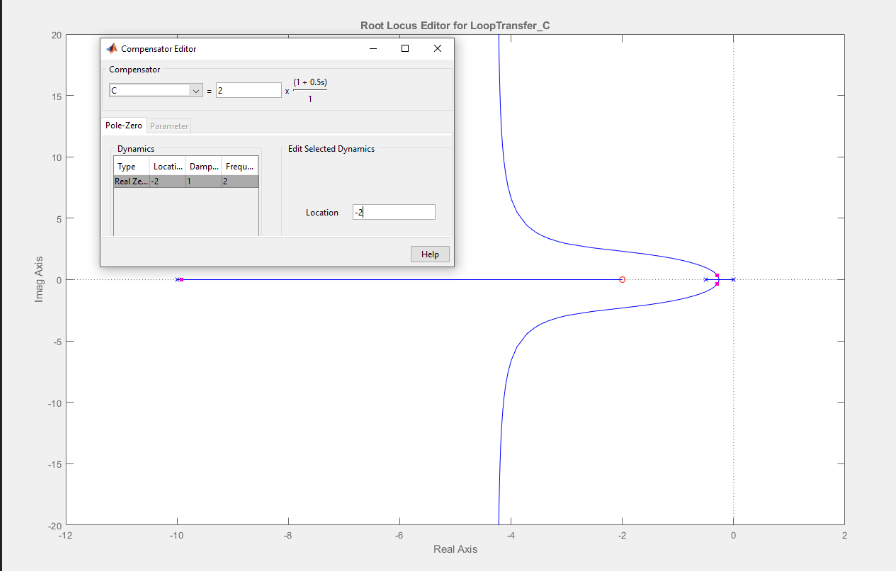

**Zero @ -1.5**

### 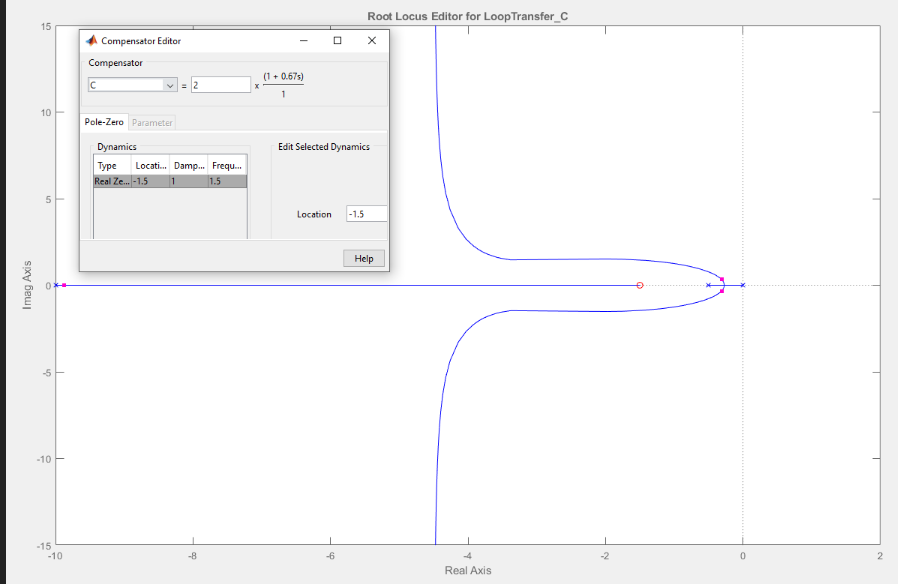

**Zero @ -1.37**

### 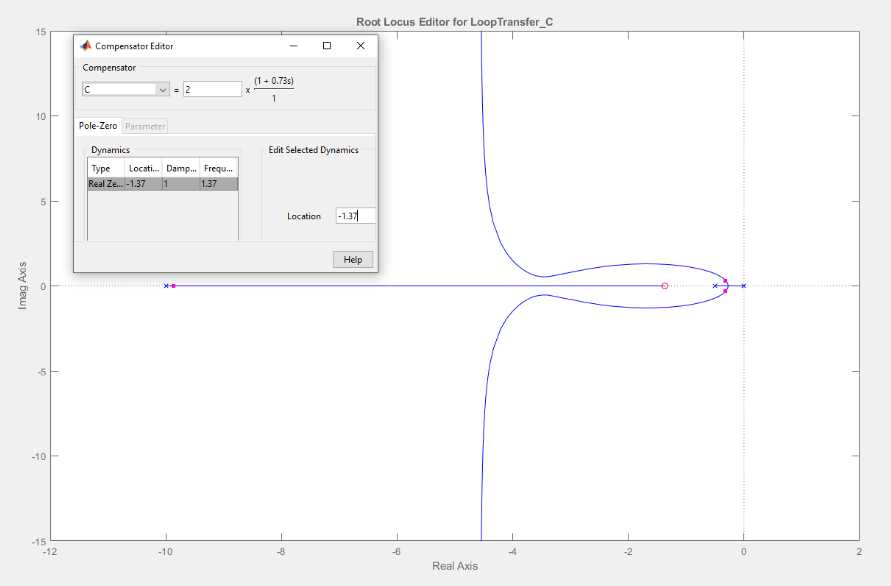

**Zero @ -1.2**

### 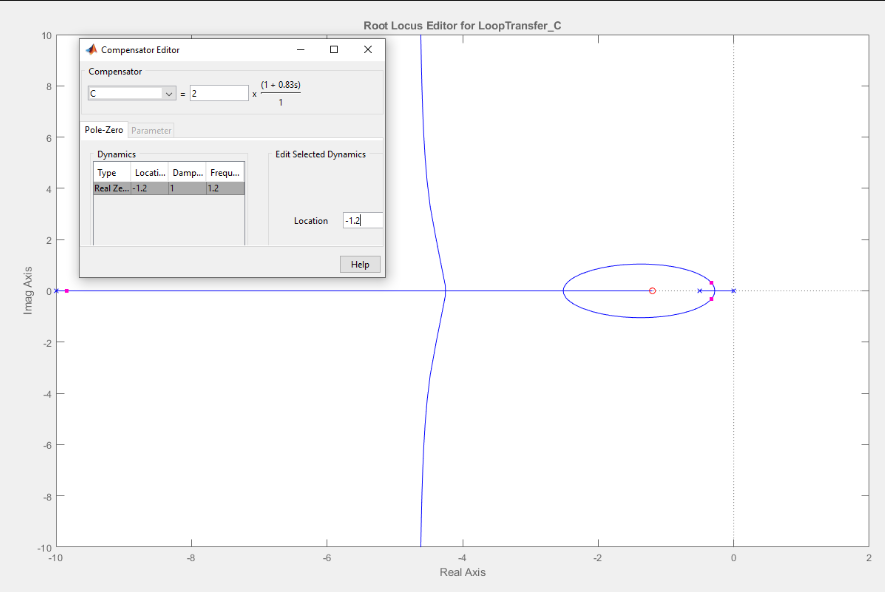

### Problem 2

*Using MATLAB's SISO Design Tool, set up a negative unity feedback system with *$G(s) = \frac{K(s+1.5)}{s(s+0.5)(s+10)}$* to produce a root locus. Open the LTI Viewer for SISO Design Tool to show step responses. Using the values of K specified in Prelab 2, record the percent overshoot and settling time and print the root loci and step response for each value of K.*

s = tf("s");
C = 20;
G = (s+1.5)/((s)*(s+0.5)*(s+10));
%controlSystemDesigner(G,C,1,1);

**K = 20**

%OS: 18.4%

T_s: 2.64s

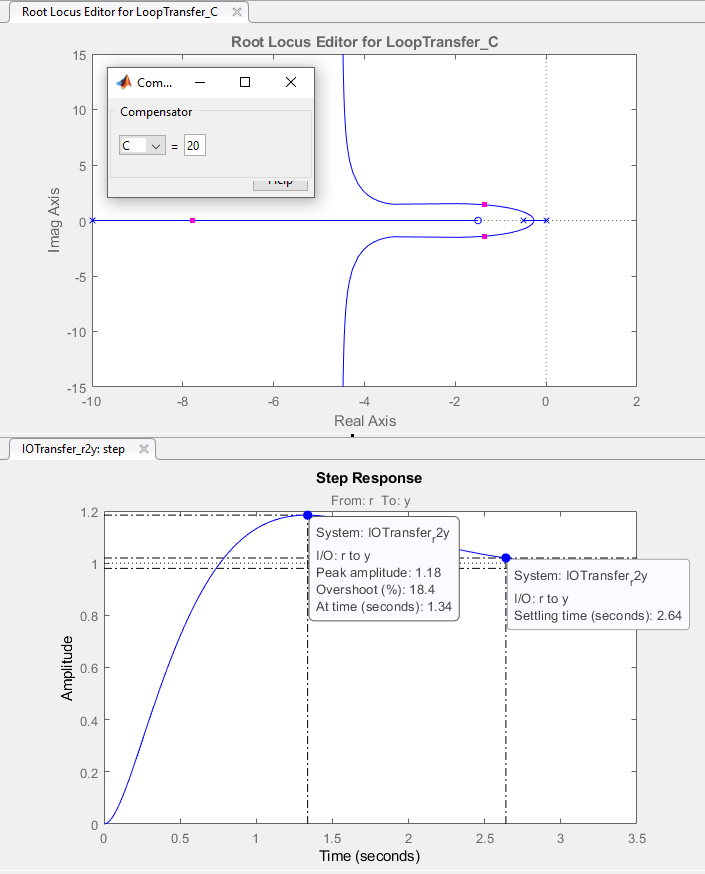

**K = 50**

%OS = 20.4%

T_s = 1.54s

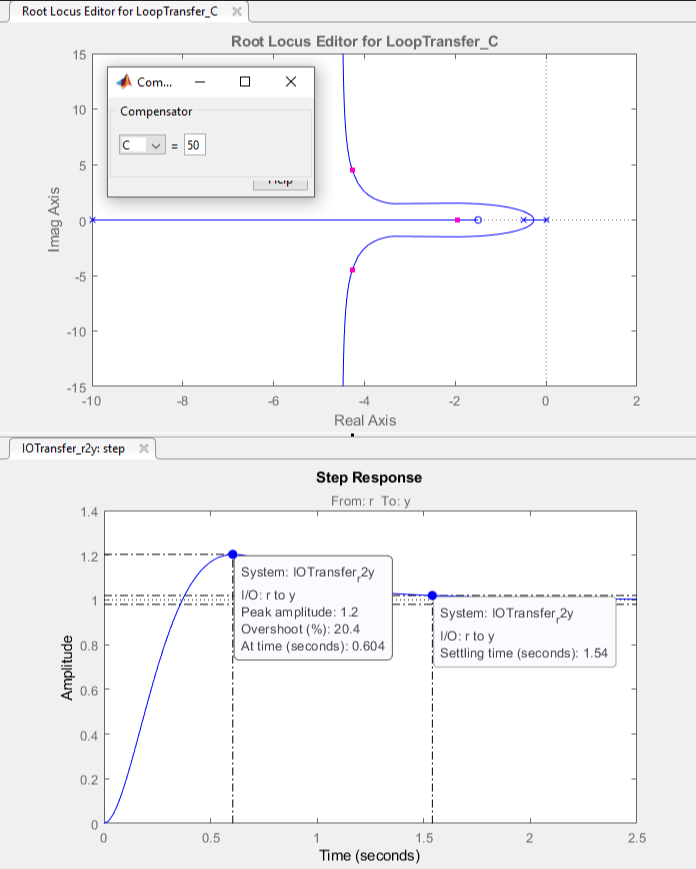

**K=85**

%OS: 25.9%

T_s: 1.34

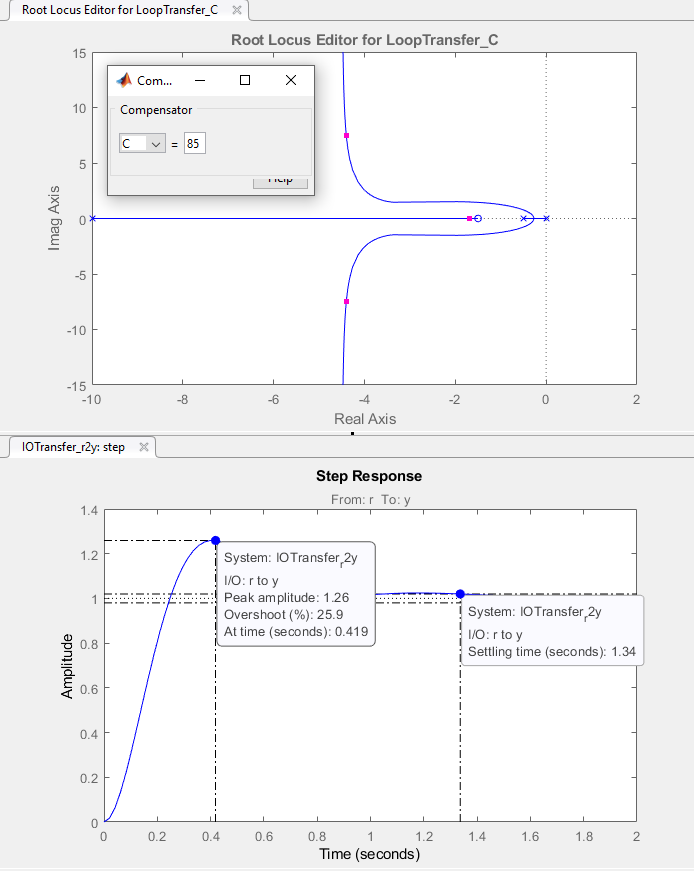

**K = 200**

%OS: 39.4

T_s = 0.845

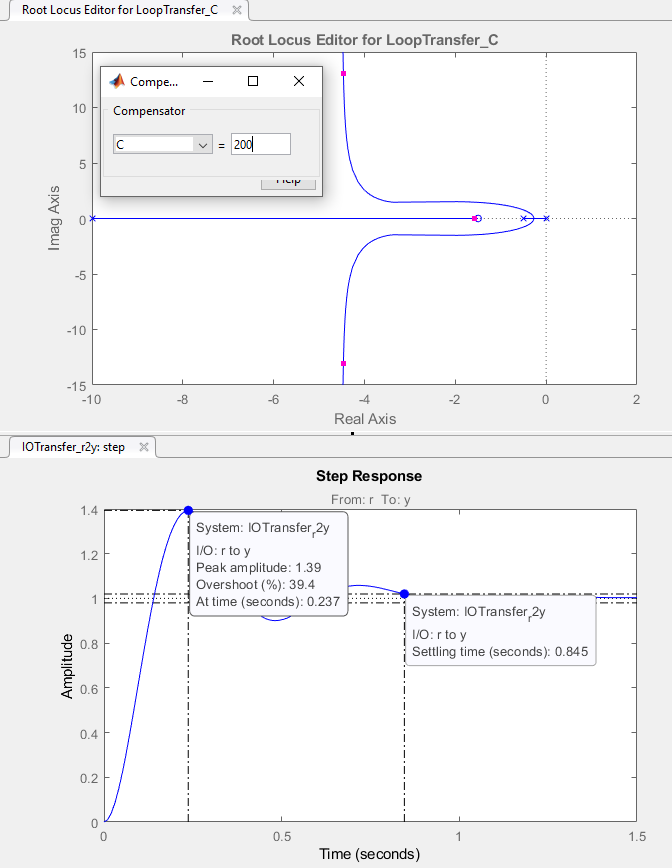

**K = 700**

%OS: 59.7%

T_s: 0.878

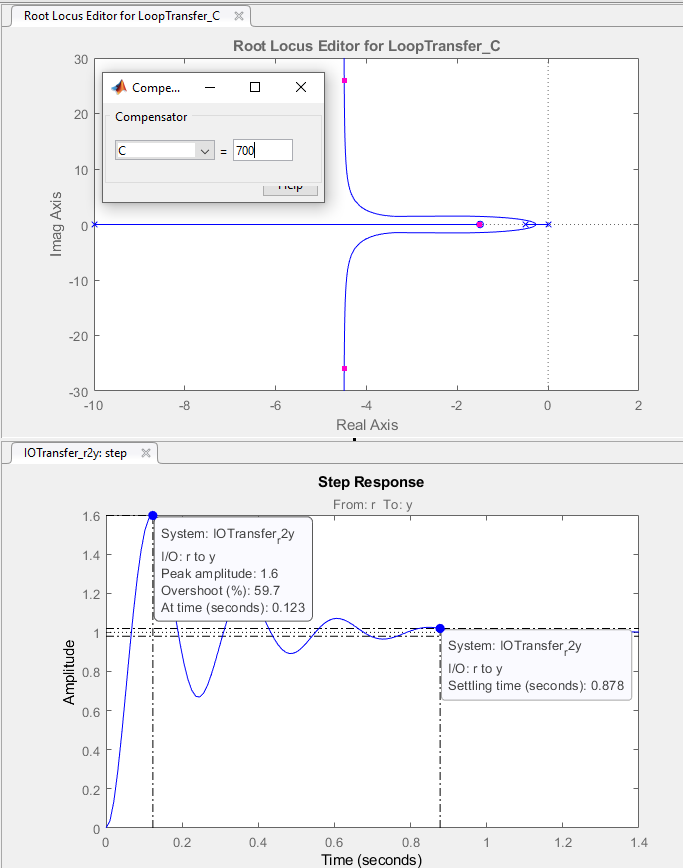

## Postlab

### Problem 1

*Discuss your findings from Prelab 1 and Lab 1. What conclusions can you draw?*

Through examination of the root locus plots in Lab 1, it can be seen that moving the location of the zeros and poles around signifigantly changes the charecteristics of the root locus. In lab 1, there were two poles next to each other with a root locus path in between them. To the left of these poles was a zero. It was seen as the zero got closer and closer the two poles on the right hand side, the curve began to bend around the zero before taking off towards infinity at -4.5 toward the complex direction. As the zero got closer and closer to the pole, the path in which the poles exit the real axis was observed to bend more and more around the zero. Eventually, the poles enclose the zero and reenter the x-axis before taking off again at -4.5. In the other direction, as the zero got farther and farther way from the two poles, the curve at which the poles take to -4.5 where they take off to infinity becomes wider and wider. Overall, this exercise shows that the strategic placement of zeros can be used to manipulate the charecteristics of a system at a given gain.

### Problem 2

*Make a table comparing percent overshoot and settling time from your calculations in Prelab 2 and your experimental values found in Lab 2. Discuss the reasons for any discrepancies. What conclustions can you draw?*

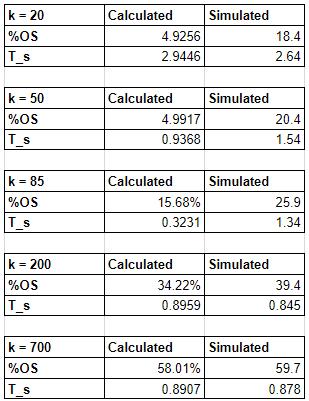

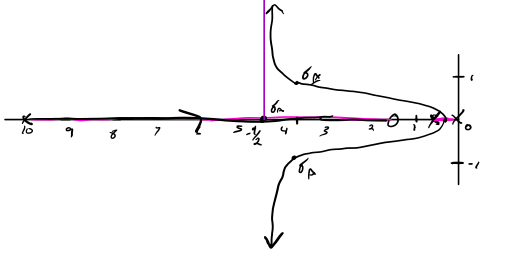

At lower values of k, the differences between the calculated and simulated values are larger. For instance, at k=20, the calculated %OS is 4.92% whereas the simulated is 18.4%. These differences could be explained due to the zero that is resting near the poles of the system. When a zero is very close to the poles of a system, the system behaves a lot like its derivitive. In addition, a zero adds gain to the system. Both of these factors have the potential of increasing the settling time and percent overshoot. As the pole moves towards the zero, this effect is minimizes as the pole begins to cancel out the effect that the zero is having on the system. Therefore, as the third pole gets closer and closer to the zero, the system begins to behave more and more like a second order system with no nearby poles and the estimations of %OS and settling time become more accurate. At a gain of 700, the second order approximation is within 0.02s of the correct settling time and less than 1% to the correct %OS. 